clc
clear

P10 = [6 3 11 7 8 5 1 2 4 9 10];



tr = [0	2	1	0	0	0	0	0	1	2	2
    2	0	2	1	0	0	0	0	2	1	1
    1	2	0	2	1	0	0	1	1	0	0
    0	1	2	0	2	1	0	1	0	0	0
    0	0	1	2	0	2	1	1	0	0	0
    0	0	0	1	2	0	2	2	0	0	0
    0	0	0	0	1	2	0	2	0	0	0
    0	0	1	1	1	2	2	0	0	0	0
    1	2	1	0	0	0	0	0	0	2	1
    2	1	0	0	0	0	0	0	2	0	2
    2	1	0	0	0	0	0	0	1	2	0];

dst = [0	2	0	0	0	0	0	0	0	1	0
    2	0	0	-1	0	0	0	1	0	0	0
    0	0	0	0	0	0	0	0	0	0	-2
    0	-1	0	0	0	0	0	0	-2	0	-2
    0	0	0	0	0	2	0	0	0	0	-2
    0	0	0	0	2	0	-2	0	0	0	1
    0	0	0	0	0	-2	0	0	1	0	-2
    0	1	0	0	0	0	0	0	-2	0	0
    0	0	0	-2	0	0	1	-2	0	2	0
    1	0	0	0	0	0	0	0	2	0	0
    0	0	-2	-2	-2	1	-2	0	0	0	0];


[MV, Pl] = SubOptPlacMaxMV(P10, dst, tr)

clear

tr = [0	2	1	0	0	0	0	0	0	0	0	0	0	0	1	2	2
    2	0	2	1	0	0	0	0	0	0	0	0	0	0	2	1	1
    1	2	0	2	0	0	0	0	0	0	0	0	0	0	1	0	0
    0	1	2	0	1	0	0	0	0	0	0	0	0	0	1	0	0
    0	0	0	1	0	2	1	0	0	1	2	0	0	1	1	0	0
    0	0	0	0	2	0	2	1	1	2	1	0	0	0	0	0	0
    0	0	0	0	1	2	0	2	2	1	0	0	0	0	0	0	0
    0	0	0	0	0	1	2	0	2	1	0	0	0	0	0	0	0
    0	0	0	0	0	1	2	2	0	2	1	0	0	0	0	0	0
    0	0	0	0	1	2	1	1	2	0	2	0	0	0	0	0	0
    0	0	0	0	2	1	0	0	1	2	0	1	1	1	0	0	0
    0	0	0	0	0	0	0	0	0	0	1	0	2	1	0	0	0
    0	0	0	0	0	0	0	0	0	0	1	2	0	2	0	0	0
    0	0	0	0	1	0	0	0	0	0	1	1	2	0	1	0	0
    1	2	1	1	1	0	0	0	0	0	0	0	0	1	0	2	1
    2	1	0	0	0	0	0	0	0	0	0	0	0	0	2	0	2
    2	1	0	0	0	0	0	0	0	0	0	0	0	0	1	2	0];


dst = [0	2	0	0	0	0	0	0	0	1	0	0	0	0	1	-1	0
    2	0	0	-1	0	0	0	1	0	0	0	0	0	0	1	0	0
    0	0	0	0	0	0	0	0	0	0	-2	0	0	0	0	0	0
    0	-1	0	0	0	0	0	0	-2	0	-2	1	0	0	2	0	0
    0	0	0	0	0	2	0	0	0	0	-2	0	0	0	0	0	0
    0	0	0	0	2	0	-2	0	0	0	1	0	0	0	0	0	0
    0	0	0	0	0	-2	0	0	1	0	-2	-2	0	0	1	-2	0
    0	1	0	0	0	0	0	0	-2	0	0	0	1	0	-2	0	0
    0	0	0	-2	0	0	1	-2	0	2	0	0	0	0	2	0	0
    1	0	0	0	0	0	0	0	2	0	0	0	0	1	0	0	0
    0	0	-2	-2	-2	1	-2	0	0	0	0	-2	0	0	-2	2	0
    0	0	0	1	0	0	-2	0	0	0	-2	0	0	0	2	0	-2
    0	0	0	0	0	0	0	1	0	0	0	0	0	0	0	1	0
    0	0	0	0	0	0	0	0	0	1	0	0	0	0	-2	0	0
    1	1	0	2	0	0	1	-2	2	0	-2	2	0	-2	0	0	0
    -1	0	0	0	0	0	-2	0	0	0	2	0	1	0	0	0	1
    0	0	0	0	0	0	0	0	0	0	0	-2	0	0	0	1	0
    ];

MVs = [];
PLs = [];

iter = 20480

iter = 20480


for i = 1:iter

    P10 = randperm(length(tr));

    [SubOptMV, SubOptPl] = SubOptPlacMaxMV(P10, tr, dst);


    MVs(end+1) = SubOptMV;
    PLs(end+1, :) = SubOptPl;


end



lt42 = MVs(MVs > 41)

lt42 =     42    42    42    42    42    42    42


I = find(MVs==42)

I =          444         790        2454        4597        6739       13978       15738



PL42 = [];

for g = 1:length(I)
    PL42(end+1, :) = PLs(I(g), :);
end

PL42

PL42 =      9    10    14    13     4     3     5     2     6     7     1    12    15     8    11    16    17
     6     5    14    13     3     2    10     4     9     7    17    12    15     8    11    16     1
     6     5    14    12     4     3    10     2     9     7     1    13    15     8    11    16    17
     6     5    14    12     4     3    10     2     9     7     1    13    15     8    11    16    17
     6     5    12    13     3     4    10    15     9     7    17    14    16     8    11     1     2
     6     5    14    13     4     3    10    15     9     7     1    12     2     8    11    17    16
     6     5    14    13     3     2    10     4     9     7    17    12    15     8    11    16     1



MV42 = [];

for c = 1:length(I)
    MV42(end+1) = Maalfkt(PL42(c,:), tr, dst);
end

MV42

MV42 =     42    42    42    42    42    42    42


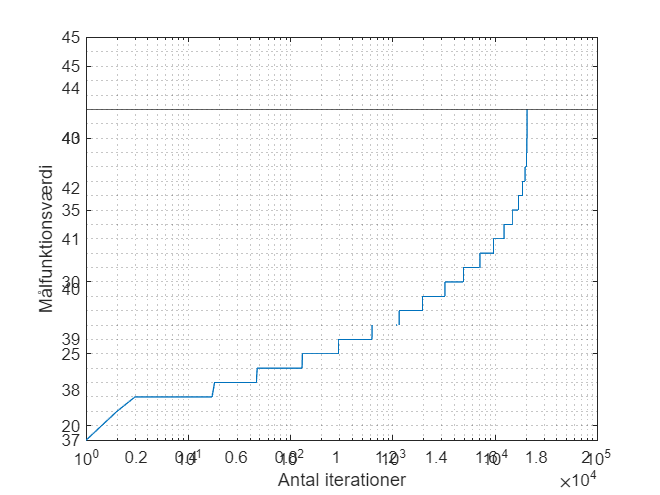



%%%%%%%%%%%

MVsplot = sort(MVs);

xlin = linspace(1,iter, iter);


plot(xlin, MVsplot), grid("minor"), ylim([min(MVsplot), max(MVsplot)+5])
yline(42), set(gca, 'XScale', 'log')

clear

tr = [0	2	1	0	0	0	0	0	0	0	0	0	0	0	1	2	2
    2	0	2	1	0	0	0	0	0	0	0	0	0	0	2	1	1
    1	2	0	2	0	0	0	0	0	0	0	0	0	0	1	0	0
    0	1	2	0	1	0	0	0	0	0	0	0	0	0	1	0	0
    0	0	0	1	0	2	1	0	0	1	2	0	0	1	1	0	0
    0	0	0	0	2	0	2	1	1	2	1	0	0	0	0	0	0
    0	0	0	0	1	2	0	2	2	1	0	0	0	0	0	0	0
    0	0	0	0	0	1	2	0	2	1	0	0	0	0	0	0	0
    0	0	0	0	0	1	2	2	0	2	1	0	0	0	0	0	0
    0	0	0	0	1	2	1	1	2	0	2	0	0	0	0	0	0
    0	0	0	0	2	1	0	0	1	2	0	1	1	1	0	0	0
    0	0	0	0	0	0	0	0	0	0	1	0	2	1	0	0	0
    0	0	0	0	0	0	0	0	0	0	1	2	0	2	0	0	0
    0	0	0	0	1	0	0	0	0	0	1	1	2	0	1	0	0
    1	2	1	1	1	0	0	0	0	0	0	0	0	1	0	2	1
    2	1	0	0	0	0	0	0	0	0	0	0	0	0	2	0	2
    2	1	0	0	0	0	0	0	0	0	0	0	0	0	1	2	0];


dst = [0	2	0	0	0	0	0	0	0	1	0	0	0	0	1	-1	0
    2	0	0	-1	0	0	0	1	0	0	0	0	0	0	1	0	0
    0	0	0	0	0	0	0	0	0	0	-2	0	0	0	0	0	0
    0	-1	0	0	0	0	0	0	-2	0	-2	1	0	0	2	0	0
    0	0	0	0	0	2	0	0	0	0	-2	0	0	0	0	0	0
    0	0	0	0	2	0	-2	0	0	0	1	0	0	0	0	0	0
    0	0	0	0	0	-2	0	0	1	0	-2	-2	0	0	1	-2	0
    0	1	0	0	0	0	0	0	-2	0	0	0	1	0	-2	0	0
    0	0	0	-2	0	0	1	-2	0	2	0	0	0	0	2	0	0
    1	0	0	0	0	0	0	0	2	0	0	0	0	1	0	0	0
    0	0	-2	-2	-2	1	-2	0	0	0	0	-2	0	0	-2	2	0
    0	0	0	1	0	0	-2	0	0	0	-2	0	0	0	2	0	-2
    0	0	0	0	0	0	0	1	0	0	0	0	0	0	0	1	0
    0	0	0	0	0	0	0	0	0	1	0	0	0	0	-2	0	0
    1	1	0	2	0	0	1	-2	2	0	-2	2	0	-2	0	0	0
    -1	0	0	0	0	0	-2	0	0	0	2	0	1	0	0	0	1
    0	0	0	0	0	0	0	0	0	0	0	-2	0	0	0	1	0
    ];

x = 5;

xs = [];

iter = 12;

for i = 1:iter
    x = x*2;
    xs(end+1) = x;
end

xs

MVs = [];

for j = 1:iter
    [MSubPL, MSubMV] = MSubOptPlacMaxMV(tr, dst, xs(j));

    MVs(end+1) = MSubMV;

end

MVs


plot(xs, sort(MVs))
ylim([min(MVs), 45])
xlim([min(xs), max(xs)])

set(gca, 'XScale', 'log')

grid("minor")

xlabel("Antal iterationer"), ylabel("Målfunktionsværdi")